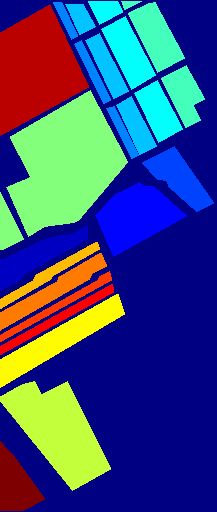

clear;
clc;
close all;
addpath('D:\Matlab\Data');
HSI = importdata('Data\PaviaC.mat');
HSI_gt = importdata('Data\PaviaC_gt.mat');

% Pavia Centering
% HSI = HSI(280:600, 380:540, :);
% HSI_gt = HSI_gt(280:600, 380:540, :);
% HSI = HSI(1:1.5:end, 1:1.5:end, :);
% HSI_gt = HSI_gt(1:1.5:end, 1:1.5:end);
% HSI = HSI(1:3:end, 1:3:end, :);
% HSI_gt = HSI_gt(1:3:end, 1:3:end);


% PaviaU:0.55,1:0.1:5,normalize,k=10,Neighbor=1200,NMF=7
% HSI_gt = double(HSI_gt);
% % HSI = HSI(1:1.3:end, 1:1.3:end, :);
% % HSI_gt = HSI_gt(1:1.3:end, 1:1.3:end);

% Salinas:0.7,1:0.1:7,no normalization,k=17,Neighbor=1200,MNF11,W+W'
% SalinasA:0.3,1:0.1:10,no normalization,k=15,Neighbor=1000,no MNF
HSI(:, :, 224) = [];
HSI(:, :, 154:167) = [];
HSI(:, :, 108:112) = [];
% % HSI = HSI(1:2:end, 1:2:end, :);
% % HSI_gt = HSI_gt(1:2:end, 1:2:end);

% Indian_pines(0.2,1:0.05:5,normalize,k=16,Neighbor=1000,MNF7)
% HSI(:, :, 220) = [];
% HSI(:, :, 150:163) = [];
% HSI(:, :, 104:108) = [];
% % HSI = HSI(1:2:end, 1:2:end, :);
% % HSI_gt = HSI_gt(1:2:end, 1:2:end);

gt = double(HSI_gt(:));
nall = length(gt);
loc = find(HSI_gt ~= 0);
gtnum = length(unique(gt)) -1;
gt_nobg = gt;
gt_nobg(gt_nobg == 0) = [];

imshow(HSI_gt, [], 'Border', 'tight');
colormap('jet');

% impixelinfo;

% HSI_gt(HSI_gt == 4) = 100;
% HSI_gt(HSI_gt == 0) = 4;
% HSI_gt(HSI_gt == 100) = 0;
% 
% imshow(HSI_gt, [], 'Border', 'tight');
% colormap('jet');
% impixelinfo;

% MNF
% coor_unknown = find(gt == 0);
% X(gt == 0, :) = 0;
% HSI = reshape(X, [row, col, L]);

sel_num = 17;

HSI = MNF(HSI);
HSI = HSI(:, :, 1:sel_num);

X = MNF(HSI);
X = X(:, :, 1:1);

% [reconst, A] = mnf(X, row, col, sel_num);
% X = reconst * A;
% % X = reshape(X, [row, col, sel_num]);

% 若已有SLIC结果
L =  importdata('D:\Matlab\SSCCE\results\Salinas\spatial_result300.mat');

% 图像空域归一化到255
X = mat2gray(X)*255;

[n, m, l] = size(X);

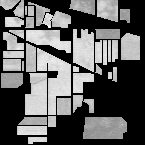

% 背景设置为-255
X = X(:);
X(gt == 0) = -255;
X = reshape(X, [n, m, l]);

imshow(X, [], 'Border', 'tight');

% impixelinfo;

% SLIC图像空域分割
[L, N] = superpixels(X, 100);

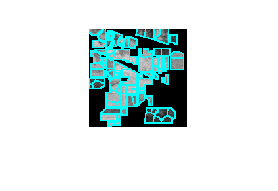

% 空域分割结果
X(gt == 0) = -1;

I = uint8(mat2gray(X)*255);
figure;
BW = boundarymask(L);
imshow(imoverlay(I, BW, 'cyan'), 'InitialMagnification', 67);

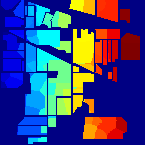


L(gt == 0) = 0;
imshow(L, [], 'Border', 'tight');
colormap('jet');


% figure;
% BW = boundarymask(L);
% imshow(imoverlay(RGB, BW, 'cyan'), 'InitialMagnification', 67);
% % colormap('colorcube');

% 空域中每一类计算平均光谱
Y = HSI;

% 归一化
[~, ~, l] = size(Y);
Y = reshape(Y, [], l);

m1 = max(Y, [], 1);
m2 = min(Y, [], 1);
Y = (Y - m2) ./ (m1 - m2);

L = L(:);
L(gt == 0) = -1;
num_spa = unique(L);
num_spa(num_spa == -1) = [];

out = zeros(length(num_spa), l);
for i = 1:length(num_spa)
    s = find(L == num_spa(i));
    spec = Y(s, :);
    out(i, :) = mean(spec);
end

% 方式二
Y2 = HSI;

% 归一化
Y2 = reshape(Y2, [], l);

m1 = max(Y2, [], 1);
m2 = min(Y2, [], 1);
Y2 = (Y2 - m2) ./ (m1 - m2);

out2 = zeros(length(num_spa), l);
for i = 1:length(num_spa)
    s = find(L == num_spa(i));
    spec = Y2(s, :);
    
    if length(s) ~= 1 
        D = squareform(pdist(spec));
        W = exp(-(D / 0.3).^2);
        T = 1./sum(W);
        W = sqrt(T)' .* W .* sqrt(T);

        Wk = W ^ 10000;

        [~, idx] = max(Wk, [], 1);
        c = find((1:length(s)) == idx)';
        
        nei = 1;
        if (2*nei+1) < length(s)
            if (c(1)-nei) >= 1 && (c(1)+nei) <= length(s)
                tmp = spec((c(1)-nei):(c(1)+nei), :);                         
            end
            
            if (c(1)-nei) < 1
                tmp = spec(1:(c(1)+nei), :);
            end
            
            if (c(1)+nei) > length(s)
                tmp = spec((c(1)-nei):end, :);
            end                
        else
            tmp = mean(spec);         
        end
        
        out2(i, :) = mean(tmp);
        

    else
        out2(i, :) = spec;
    end
end

% 光谱聚类一
Z = out;

m1_Z = max(Z, [], 1);
m2_Z = min(Z, [], 1);
Z = (Z - m2_Z) ./ (m1_Z - m2_Z);

% 光谱聚类二
Z2 = out2;

m1_Z2 = max(Z2, [], 1);
m2_Z2 = min(Z2, [], 1);
Z2 = (Z2 - m2_Z2) ./ (m1_Z2 - m2_Z2);

sigma = 0.6;

% CCE1
v = CCE_cnum(Z, sigma, 1, 0.01, 100);

% CCE2
v2 = CCE_cnum(Z2, sigma, 1, 0.01, 100);

[result_cce, ~, ~, ~, ~] = CCE(Z, sigma, 1, 0.01, 100, gtnum);
[result_cce2, ~, ~, ~, ~] = CCE(Z2, sigma, 1, 0.01, 100, gtnum);

% 标签对应
ind = L;
ind(gt == 0) = [];

lab = ind;
tmp = sort(unique(ind));
k = 1;
for i = 1:length(tmp)
    lab(ind == tmp(i)) = k;
    k = k + 1;
end
k = k - 1;

cce = zeros(length(lab), 1);

for i = 1:length(lab)
    cce(i) = result_cce(lab(i));
end

cce2 = zeros(length(lab), 1);

for i = 1:length(lab)
    cce2(i) = result_cce2(lab(i));
end

% 显示
gt_nobg = gt;
gt_nobg(gt_nobg == 0) = [];
[~, cce] = label_corrected(cce, gt_nobg);
[OA_cce, Kappa, PA, UA] = calaccuracy(gt_nobg, cce)

OA_cce = 0.8151

Kappa = 0.7909

PA =     0.9985
    0.9997
    1.0000
    0.9835
    0.9604
    0.9957
    0.9994
    1.0000
    0.9998
    0.6434


UA =     1.0000
    1.0000
    1.0000
    0.9183
    1.0000
    1.0000
    1.0000
    0.5746
    1.0000
    1.0000


[ARI_cce, ~, ~, ~] = ari(gt_nobg, cce)

ARI_cce = 0.6922


[~, cce2] = label_corrected(cce2, gt_nobg);
[OA_cce2, Kappa, PA, UA] = calaccuracy(gt_nobg, cce2)

OA_cce2 = 0.6813

Kappa = 0.6391

PA =     0.9985
    0.9487
         0
         0
    1.0000
    0.9960
    1.0000
    0.9996
    1.0000
    0.3920


UA =     1.0000
    1.0000
         0
         0
    0.5831
    1.0000
    1.0000
    0.6070
    0.7891
    0.2762


[ARI_cce2, ~, ~, ~] = ari(gt_nobg, cce2)

ARI_cce2 = 0.6783

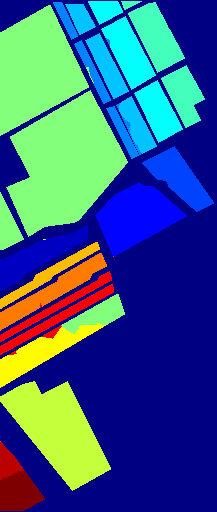

[n, m, l] = size(X);
img_cce = zeros(nall, 1);
img_cce(loc, :) = cce;
img_cce = reshape(img_cce, [], m);
imshow(img_cce, [], 'Border','tight');
colormap('jet');

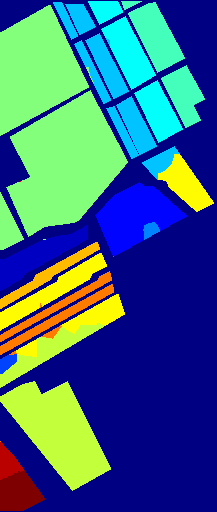


img_cce2 = zeros(nall, 1);
img_cce2(loc, :) = cce2;
img_cce2 = reshape(img_cce2, [], m);
imshow(img_cce2, [], 'Border','tight');
colormap('jet');

img_cce = zeros(nall, 1);
img_cce(loc, :) = cce;
img_cce = reshape(img_cce, [], m);
imshow(img_cce, [], 'Border','tight');
colormap('jet');

print('C:\Users\xdzha\Desktop\Figures\Section5\Salinas\sscce2.svg', '-dsvg');

% % 结合SLIC的KCCE
% cnum = 100;
% [ind_kmeans, C] = kmeans(Z, cnum, 'Replicates', 1);
% 
% v_sskcce = CCE_cnum(C, sigma, 1, 0.01, 20);

% [result_kcce, ~, ~, ~, ~] = CCE(C, sigma, 1, 0.01, 20, gtnum);

% kcce2 = zeros(k, 1);
% 
% for i = 1:k
%     kcce2(i) = result_kcce(ind_kmeans(i));
% end
% 
% kcce = zeros(length(lab), 1);
% 
% for i = 1:length(lab)
%     kcce(i) = kcce2(lab(i));
% end

% % 显示
% [map, kcce] = label_corrected(kcce, gt_nobg);
% [OA, Kappa, PA, UA] = calaccuracy(gt_nobg, kcce)
% [ARI_kcce, ~, ~, ~] = ari(gt_nobg, kcce)

% figure;
% 
% img_kcce = zeros(nall, 1);
% img_kcce(loc, :) = kcce;
% img_kcce = reshape(img_kcce, [], m);
% imshow(img_kcce, [], 'Border','tight');
% colormap('jet');

% % 结合SLIC的LMCCE
% k = 19;
% 
% sigma = 0.2;
% D = squareform(pdist(Z))  ;
% W = exp(-(D / sigma).^2);
% % T = 1./sum(W);
% % W = sqrt(T)' .* W .* sqrt(T);
% 
% [H, ~] = symnmf_anls(W, k, ['var']);
% 
% 
% v_sslmcce = SymNMF_CCE_cnum(H, 1, 0.005, 5);
% 
% 
% [result_sslmcce, ~, ~, ~, ~] = SymNMF_CCE(H, 1, 0.005, 5, gtnum);
% 
% 
% sslmcce = zeros(length(lab), 1);
% 
% for i = 1:length(lab)
%     sslmcce(i) = result_sslmcce(lab(i));
% end
% 
% 
% [~, sslmcce] = label_corrected(sslmcce, gt_nobg);
% [OA, Kappa, PA, UA] = calaccuracy(gt_nobg, sslmcce)
% [ARI_sslmcce, ~] = ari(gt_nobg, sslmcce)

% figure;
% 
% img_sslmcce = zeros(nall, 1);
% img_sslmcce(loc, :) = sslmcce;
% img_sslmcce = reshape(img_sslmcce, [], m);
% imshow(img_sslmcce, [], 'Border','tight');
% colormap('jet');